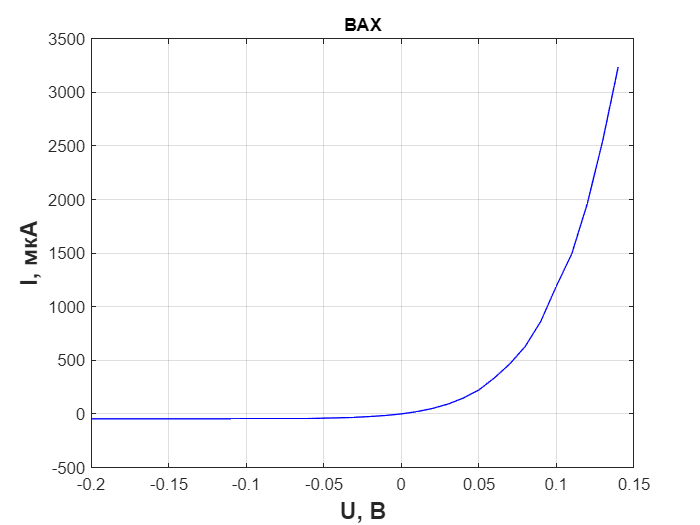

cla reset;
U =  -0.2:0.01:0.14;
I = [-46.3 -46.3 -46.3 -46.3 -46.3  -46.2 -46.1 -46.1 -45.9 -45.7 -44.9 -44.3 -44.3 -44.1 -44  -39.5 -36.5 -31.5 -24.5 -14.5 0 20.9 50.5 91.2 147.4 223 335 466 630 863 1190 1493 1960 2550 3240];
plot(U, I, 'Color', 'blue');
grid on;
title('ВАХ');
ylabel('I, мкА','FontSize',14,'FontWeight','bold');
xlabel('U, В','FontSize',14,'FontWeight','bold');

% saveas(gcf,'f60_plot_table_VAX.png');
Is = zeros(1, 35)

Is =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


q = 1.6 * 1e-19; k = 1.38 * 1e-23; T = 297.5;
mu = q/(k*T)

mu = 38.9721

for v = 1:1:35
    Is(v) = mu*U(v);
end
Is

Is =    -7.7944   -7.4047   -7.0150   -6.6253   -6.2355   -5.8458   -5.4561   -5.0664   -4.6767   -4.2869   -3.8972   -3.5075   -3.1178   -2.7280   -2.3383   -1.9486   -1.5589   -1.1692   -0.7794   -0.3897         0    0.3897    0.7794    1.1692    1.5589    1.9486    2.3383    2.7280    3.1178    3.5075    3.8972    4.2869    4.6767    5.0664    5.4561


qkT  = (Is(35) - Is(1))/(U(35) - U(1))

qkT = 38.9721

qk = qkT*T

qk = 1.1594e+04

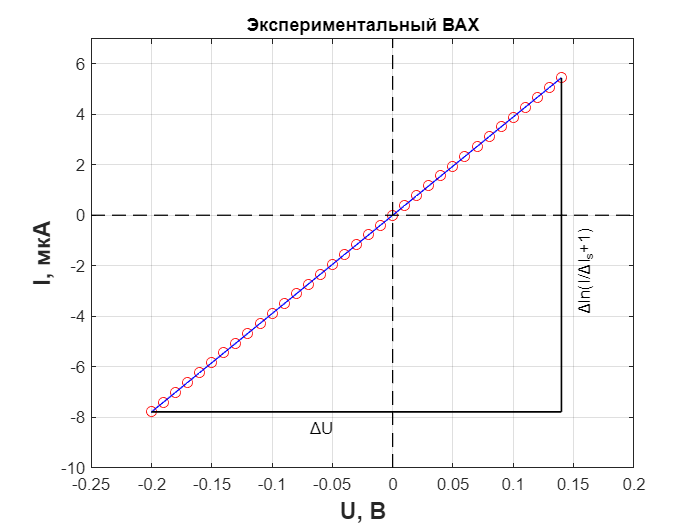

plot(U, Is, 'o', 'Color', 'red');
hold on;
plot(U, Is, 'Color', 'blue');
plot([-0.25 0.2], [0 0], '--', 'Color', 'black', 'LineWidth', 0.75)
plot([0 0], [-10 7], '--', 'Color', 'black', 'LineWidth', 0.75)
plot([U(35) U(35)], [Is(1) Is(35)], '-', 'Color', 'black', 'LineWidth', 1)
plot([U(1) U(35)], [Is(1) Is(1)], '-', 'Color', 'black', 'LineWidth', 1)
hold off;
grid on;
title('Экспериментальный ВАХ');
xlim([-0.25 0.2]);
ylim([-10 7]);
text(0.16, -4,'{\Delta}ln(I/{\Delta}I_s+1)', 'Color','black','Rotation', 90);
text(-0.07, -8.5,'{\Delta}U', 'Color','black');
ylabel('I, мкА','FontSize',14,'FontWeight','bold');
xlabel('U, В','FontSize',14,'FontWeight','bold');

% saveas(gcf,'f60_plot_VAX_e.png');
t = 25:4:53

t =     25    29    33    37    41    45    49    53


T = t + 273

T =    298   302   306   310   314   318   322   326


T_1 = 1./T

T_1 =     0.0034    0.0033    0.0033    0.0032    0.0032    0.0031    0.0031    0.0031


Is = [-0.31 -0.4 -0.57 -0.7 -0.89 -1.16 -1.44 -1.81];
IsLN = zeros(1, 8);
for v = 1:1:8
    IsLN(v) = log(exp(T(v))/exp(297.5));
end
IsLN

IsLN =     0.5000    4.5000    8.5000   12.5000   16.5000   20.5000   24.5000   28.5000


T_0 = 1/297.5;
Eg_k = IsLN(2)/(T_0 - T_1(2))

Eg_k = 8.9845e+04

Eg_k * k * (1/(1.6 * 10e-19))

ans = 0.7749

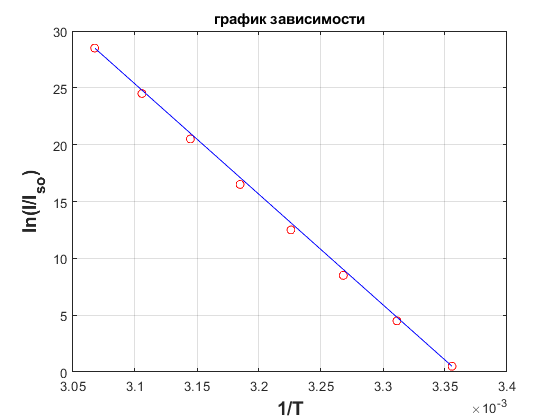

plot(T_1, IsLN, 'o', 'Color', 'red');
hold on;
plot([T_1(1) T_1(8)], [IsLN(1) IsLN(8)], 'Color', 'blue');
hold off;
grid on;
title('график зависимости');
ylabel('ln(I/I_{so})','FontSize',14,'FontWeight','bold');
xlabel('1/T','FontSize',14,'FontWeight','bold');

% saveas(gcf,'f60_plot_z2.png');